clear 
clc
%%%%%%%%%%%%%%%%%%%%
%%USING THE MODEL%%
%%%%%%%%%%%%%%%%%%%

par = param;
%Z = [x, y, psi, vx, vy, yawrate, theta, steer_angle, v_theta, ax, delta]
%u = [v_theta, accel, steer_target]
%x = [x, y, psi, vx, vy, r, theta, steer_angle] State array definition

%Current State
x_init = [0 0.5 0 5.4 0 0 0 0];
problem.xinit = x_init'; 

%Initial guess
x0i=[x_init 0, 0, 0];
x0=repmat(x0i',par.steps,1);
problem.x0=x0; 

%Path
    theta0 = 0; %Starting progress on track

    %Input
    X = [0,3,6,7.5,10,12,15,18];
    Y = [0, 0.25, 0.5, 0.75, 1, 0.75, 1, -0.5]*1.5;
    V = [6, 6.5, 7, 7.5, 8, 8.5, 9, 9.5];
    
    problem.all_parameters = repmat( spline_gen(X,Y,V) ,par.steps,1); %input_params
    
%SOLVE IT
[output, exitflag, info] = FORCES_dyn(problem); %flag: 1-sucess 0-timed out <0-error
exitflag

exitflag = 0

info.solvetime*1000

ans = 27.5873

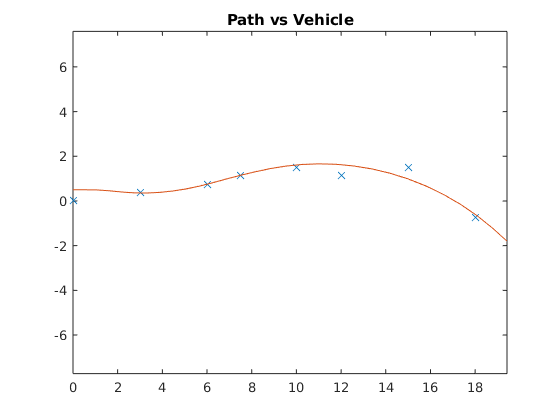


%Reorganize Output Data
n = ['x01';'x02';'x03';'x04';'x05';'x06';'x07';'x08';'x09';'x10';'x11';'x12';'x13';'x14';'x15';'x16';'x17';'x18';'x19';'x20';'x21';'x22';'x23';'x24';'x25';'x26';'x27';'x28';'x29';'x30'];
data = zeros(par.steps, par.state_vars+par.control_vars);
for i = 1:length(n)
    data(i,:)=output.(n(i,:));
end


%PLOT RESULTS
plot(X,Y,'x') %Sample path
axis('equal')
title("Path vs Vehicle")
hold on
plot(data(:,1),data(:,2)) %location on track
hold off

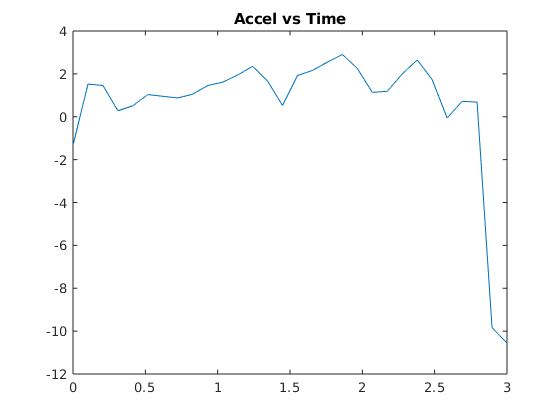


%Control
plot(linspace(0,par.horizon,par.steps), data(:,10))
title("Accel vs Time")

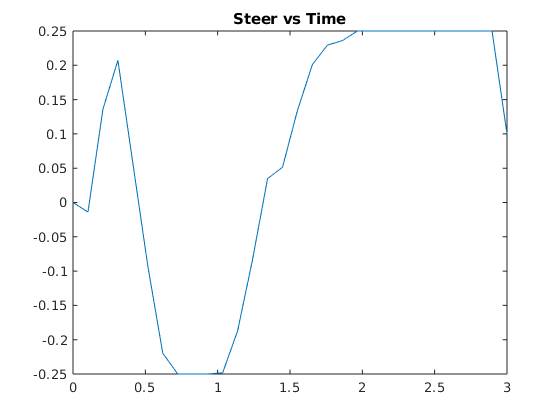

plot(linspace(0,par.horizon,par.steps), data(:,8))
title("Steer vs Time")

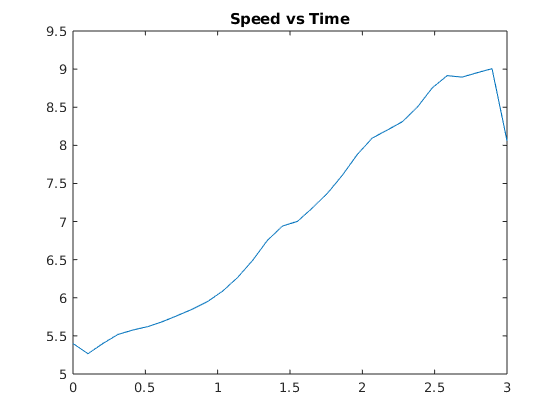



%Graph Everything Else
plot(linspace(0,par.horizon,par.steps), data(:,4))
title("Speed vs Time")

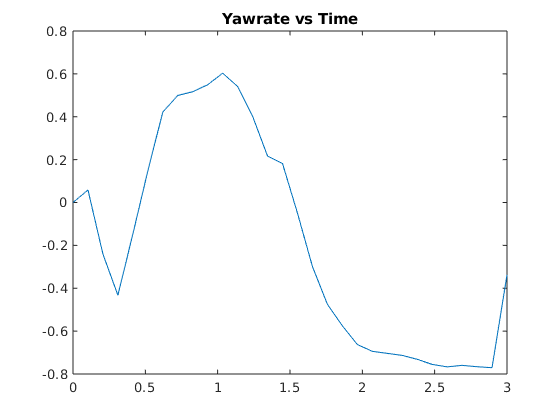

plot(linspace(0,par.horizon,par.steps), data(:,6))
title("Yawrate vs Time")

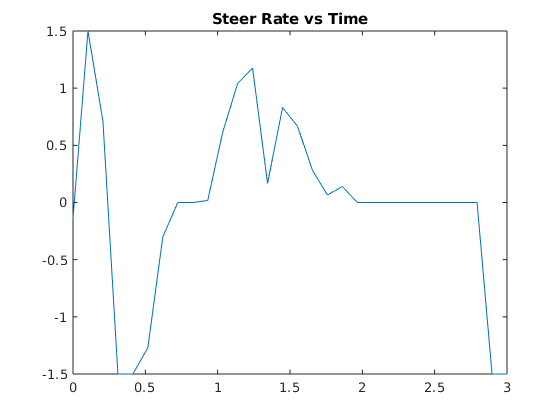

plot(linspace(0,par.horizon,par.steps), data(:,11))
title("Steer Rate vs Time")